# **Caracterización de una estructura a un modelo lineal**

Andrés José Rodríguez Torres

18 de septiembre de 2024

Ajustar al modelo de una estructura como un conjunto de masa resorte amortiguador


$$\mathbf{M_s}\ddot{\mathbf{x}}(t)+\mathbf{C_s}\dot{\mathbf{x}}(t)+\mathbf{K_s}\mathbf{x}(t)=-\mathbf{M_sl}\ddot{x}_{g}(t) 
$$


donde $M_s,\ C_s,\ K_s \ \in \mathbb{R}^{n\times n}$ matrices de masas, coeficentes de amortiguamiento y elasticidad

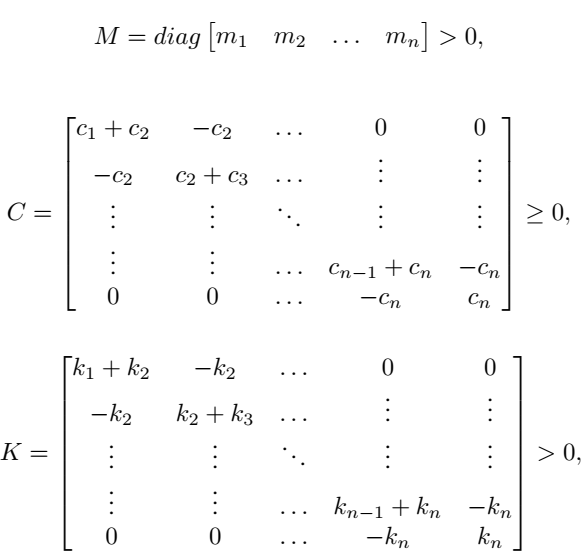

y los desplazamientos y sus derivadas, junto con un vector de distribución del sismo en todos los pisos se pueden expresar como:

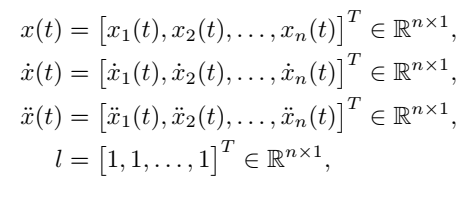

## Identificación por GA

Con la misma información del modelo y la función objetivo


$$fitness=\sum_{j=1}^{n}\frac{1}{N}\sum_{i=1}^{N}\left[(\hat{x_i}-x_i)^2\right]$$


donde n es el número de pisos y N es el número de datos que se tiene con respecto al tiempo. Por otra parte,  $\hat{x_i}$ y $x_i$ representan el desplazamiento estimado por el modelo y el medido experimentalmente.

ga stopped because it exceeded options.MaxGenerations.


g = 1.0e+04 *

    0.8377    0.8532    0.8513    0.8536    1.1734    0.0025    0.0035    0.0021    0.0013    0.0008


fval = 631.6726

exitflag = 0

output = struct with fields:
      problemtype: 'linearconstraints'
         rngstate: [1×1 struct]
      generations: 200
        funccount: 38210
          message: 'ga stopped because it exceeded options.MaxGenerations.'
    maxconstraint: 0
       hybridflag: []


ga stopped because it exceeded options.MaxGenerations.


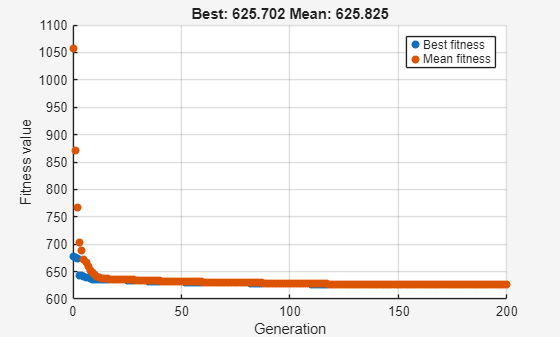

g = 1.0e+03 *

    8.1604    8.6350    8.4988    9.8307    8.9177    0.0254    0.0355    0.0216    0.0131    0.0080


fval = 625.7024

exitflag = 0

output = struct with fields:
      problemtype: 'linearconstraints'
         rngstate: [1×1 struct]
      generations: 200
        funccount: 38210
          message: 'ga stopped because it exceeded options.MaxGenerations.'
    maxconstraint: 0
       hybridflag: []


for k=1:2
    close all; clc;
    clearvars -except k
    %options = optimoptions(@particleswarm,'MaxStallIterations',10,'PlotFcns',@pswplotbestf);
    options = optimoptions('ga',...
                           'MaxGenerations', 200, ...
                           'MaxStallGenerations', 20, ...
                           'ConstraintTolerance', 1e-6, ...
                           'InitialPopulationMatrix',[ones(1,5)*8400, ones(1,5)*23],...
                           'UseParallel', true,... %);  % Habilitar paralelización
                           'PlotFcns', {@gaplotbestf});           
    
    nvars=10;
    
    lb = [7000  7000  7000  7000  7000  0   0   0   0    0]; 
    ub = [12000 12000 12000 12000 12000 100 100 100 100 100];
    A=[ 0.6 -1   0   0   0   0 0 0 0 0;
       -1.4  1   0   0   0   0 0 0 0 0;
         0  0.6 -1   0   0   0 0 0 0 0;
         0 -1.4  1   0   0   0 0 0 0 0;
         0   0  0.6 -1   0   0 0 0 0 0; 
         0   0 -1.4  1   0   0 0 0 0 0; 
         0   0   0  0.6 -1   0 0 0 0 0; 
         0   0   0 -1.4  1   0 0 0 0 0;
     
         0   0   0   0   0  0.6 -1   0   0   0; 
         0   0   0   0   0 -1.4  1   0   0   0;
         0   0   0   0   0   0  0.6 -1   0   0; 
         0   0   0   0   0   0 -1.4  1   0   0;
         0   0   0   0   0   0   0  0.6 -1   0; 
         0   0   0   0   0   0   0 -1.4  1   0;
         0   0   0   0   0   0   0   0  0.6 -1;    
         0   0   0   0   0   0   0   0 -1.4  1];
    b=zeros(16,1);
    Aeq = [];
    beq = [];
    nonlcon = [];
    %Optimización
    tic
    [g,fval,exitflag,output]=ga(@costoAcc,nvars,A,b,Aeq,beq,lb,ub,nonlcon,options)
    topt=toc;
    
    % Parametros obtenidos 
    k1=g(1); k2=g(2); k3=g(3); k4=g(4); k5=g(5);
    c1=g(6); c2=g(7); c3=g(8); c4=g(9); c5=g(10);
    
    %Datos Experimentales
    load('datosFiltradosSismoYOct8.mat','ab','xr','vr','ar','t'); %datos de los experimentos
    
    %Masas de la estructura
    M=diag([11.773 9.17 9.14 9.12 9.08]); %Masas sin conectar amortiguador
    %M=[12.5 9.17 9.15 9.11 9.08];  %Masas con amortiguador
    m1=M(1,1); m2=M(2,2); m3=M(3,3); m4=M(4,4); m5=M(5,5);
    
    Mi=inv(M);
    l=ones(5,1);
    
    Cs=[c1+c2, -c2,    0,    0,   0;
        -c2,  c2+c3, -c3,    0,   0;
        0,     -c3,  c3+c4, -c4,  0;
        0,      0,   -c4,   c4+c5,-c5;
        0,      0,     0,   -c5,   c5];
    
    Ks=[k1+k2, -k2,   0,    0,    0;
       -k2,  k2+k3, -k3,   0,    0;
         0,  -k3,  k3+k4, -k4,   0;
         0,   0,    -k4,  k4+k5,-k5;
         0,   0,      0,   -k5,  k5];
    n=5;
    
    %Space-state
    A = [zeros(n) eye(n); -Mi*Ks -Mi*Cs];
    B = [zeros(n,1); -l];
    C = [-Mi*Ks -Mi*Cs];
    
    %Dimensiones
    nx=size(A,1);
    nu=size(B,2);
    ny=size(C,1);
    D = zeros(ny,nu);
    
    x0=zeros(nx,1); %Initial conditions
    sys=ss(A,B,C,D);
    Ye=lsim(sys,ab,t,x0,'zoh');
    
    %Valores de desempeño
    MSE=zeros(1,n); RMSE=MSE; MAE=MSE; R2=MSE;  
    for i=1:n
        [MSE(i),RMSE(i),MAE(i),R2(i)]=metrics(Ye(:,i),ar(:,i));
    end
    
    txt='parametros_corrida_'+ string(k);
    save(txt,'g','fval','topt','k1','k2','k3','k4','k5','c1','c2','c3','c4','c5','R2','MAE','RMSE','MSE')
end

function fourierLocal(x,L,Fs)

Compute the Fourier transform of the signal. 

Y = fft(x);

Compute the two-sided spectrum `P2`. Then compute the single-sided spectrum `P1` based on `P2` and the even-valued signal length `L`.

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

Define the frequency domain `f` and plot the single-sided amplitude spectrum `P1`. 

freq = Fs*(0:(L/2))/L;
plot(freq,P1) 
title('Single-Sided Amplitude Spectrum of F(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')
end
